# Hardpoint Forces Calculator

Original author: Graeme Dockrill, VDX sub-team member 2022

Modified by: Liam Foster, mechanical lead 2022-2024

Description: 

This script reads suspension hardpoints and input forces from the "Brightside V2 Suspension Geometry Design" Google Sheet, plots the suspension system in 3D, and calculates the forces in each member. It assumes a left corner from the driver's perspective and therefore the right wheels are outboard and see the most load. This is the consistent with the worst case scenario as the motor wheel is on the right and therefore seeing the most load possible.

% Clear the console and all variables
clear
clc

% Choose turn direction
TurnDir = -1;
% Choose loading in gs (*9.81m/s^2)
BrakeLoadCase = 1;
CornerLoadCase = 1;
BumpLoadCase = 2;

## Initialization & Data Pulling

% ----------------Setup----------------------------------------------------

% Constants
hardpointsize = 10;
LineWidth = 1.5;
unitvect_scalefactor = 0.05;
unitvect_linewidth = 1.5;
forcevect_scalefactor = 0.00005;
forcevect_linewidth = 1.5;

% x,y,z for clearer equations
x = 1;
y = 2;
z = 3;

% Extracts balljoint coordinates from google sheets
ID = '1UxrHRz9iydKkYqhXAQWLDXY1FJoSzHCgv_TjBJgwtKQ';
sheet_name = 'Hardpoints';
url_name = sprintf('https://docs.google.com/spreadsheets/d/%s/gviz/tq?tqx=out:csv&sheet=%s',...
    ID, sheet_name);
data = webread(url_name);
coordinates = [data.X(1:32) data.Y(1:32) data.Z(1:32)];         % extract coordinates from data

% Converting values read from excel to 3D points
m_BS = coordinates(1,x:z);          % Brightside mass
m_D = coordinates(2,x:z);           % Driver mass
COM = coordinates(3,x:z);           % Center of Mass

O = coordinates(4,x:z);             % Origin
MC = coordinates(5,x:z);            % Moment Center

% Front hardpoints
F_LCA_IR = coordinates(6,x:z);      % Front LCA inboard rear rod end
F_LCA_IF= coordinates(7,x:z);       % Front LCA inboard front rod end
F_LCA_O = coordinates(8,x:z);       % Front LCA outboard ball joint
F_UCA_IR = coordinates(9,x:z);      % Front UCA inboard rear rod end
F_UCA_IF = coordinates(10,x:z);      % Front UCA inboard front rod end
F_UCA_O = coordinates(11,x:z);       % Front UCA outboard ball joint
F_PR_O = coordinates(12,x:z);        % Front pull/push rod outboard rod end
F_PR_I = coordinates(13,x:z);       % Front pull/push rod inboard rod end
F_RP = coordinates(14,x:z);         % Front rocker pivot
F_RS = coordinates(15,x:z);         % Front rocker-shock mount
F_SC = coordinates(16,x:z);         % Front shock-chassis mount
F_TR_O = coordinates(17,x:z);       % Front steering tie-rod outboard rod end
F_TR_I = coordinates(18,x:z);       % Front steering tie-rod inboard rod end
F_WC = coordinates(19,x:z);         % Front wheel center
F_TP = coordinates(20,x:z);         % Front tire contact patch

% Rear hardpoints
R_LCA_IR = coordinates(18,x:z);     % Rear LCA inboard rear rod end
R_LCA_IF= coordinates(4,x:z);       % Rear LCA inboard front rod end
R_LCA_O = coordinates(5,x:z);       % Rear LCA outboard ball joint
R_UCA_IR = coordinates(6,x:z);      % Rear UCA inboard rear rod end
R_UCA_IF = coordinates(7,x:z);      % Rear UCA inboard front rod end
R_UCA_O = coordinates(8,x:z);       % Rear UCA outboard ball joint
R_PR_O = coordinates(9,x:z);        % Rear pull/push rod outboard rod end
R_PR_I = coordinates(10,x:z);       % Rear pull/push rod inboard rod end
R_RP = coordinates(11,x:z);         % Rear rocker pivot
R_RS = coordinates(12,x:z);         % Rear rocker-shock mount
R_SC = coordinates(13,x:z);         % Rear shock-chassis mount
R_TR_O = coordinates(14,x:z);       % Rear steering tie-rod outboard rod end
R_TR_I = coordinates(15,x:z);       % Rear steering tie-rod inboard rod end
R_WC = coordinates(16,x:z);         % Rear wheel center
R_TP = coordinates(17,x:z);         % Rear tire contact patch

% Creating matrices for each part for plotting purposes
F_LCA = [F_LCA_IF; F_LCA_O; F_LCA_IR];  % Front lower control arm
F_UCA = [F_UCA_IF; F_UCA_O; F_UCA_IR];  % Front upper control arm
F_PR = [F_PR_O; F_PR_I];                % Front push/pull rod
F_R = [F_PR_I; F_RP; F_RS;];            % Front rocker
F_S = [F_RS; F_SC];                     % Front shock
F_TR = [F_TR_O; F_TR_I];                % Front steering tie-rod

R_LCA = [R_LCA_IF; R_LCA_O; R_LCA_IR];  % Rear lower control arm
R_UCA = [R_UCA_IF; R_UCA_O; R_UCA_IR];  % Rear upper control arm
R_PR = [R_PR_O; R_PR_I];                % Rear push/pull rod
R_R = [R_PR_I; R_RP; R_RS];             % Rear rocker
R_S = [R_RS; R_SC];                     % Rear shock
R_TR = [R_TR_O; R_TR_I];                % Rear steering tie-rod

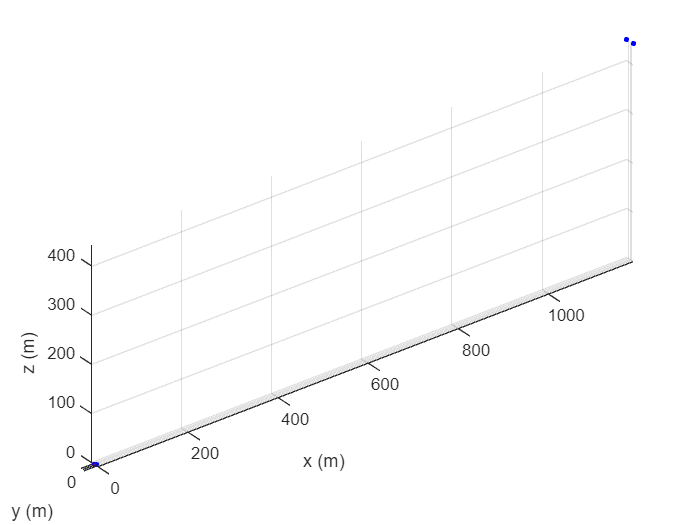

% ----------------Plotting-------------------------------------------------

% Plotting all points for control arms
% scatter3(coordinates(1:17,x), coordinates(1:17,y), coordinates(1:17,z), hardpointsize, 'filled', 'o', 'blue');
scatter3(coordinates(:,x), coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');
hold on
scatter3(coordinates(:,x), -coordinates(:,y), coordinates(:,z), hardpointsize, 'filled', 'o', 'blue');

% Drawing lines for front right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for front left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(F_LCA(:,x), -F_LCA(:,y), F_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(F_UCA(:,x), -F_UCA(:,y), F_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(F_PR(:,x), -F_PR(:,y), F_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(F_R(:,x), -F_R(:,y), F_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_S(:,x), -F_S(:,y), F_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(F_TR(:,x), -F_TR(:,y), F_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear right UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Drawing lines for rear left UCA, LCA, push/pull rod, rocker, shock, and tie rod
line(R_LCA(:,x), -R_LCA(:,y), R_LCA(:,z), 'Color','blue', 'LineWidth', LineWidth);
line(R_UCA(:,x), -R_UCA(:,y), R_UCA(:,z),'Color','blue', 'LineWidth', LineWidth);
line(R_PR(:,x), -R_PR(:,y), R_PR(:,z),'Color','black', 'LineWidth', LineWidth);
line(R_R(:,x), -R_R(:,y), R_R(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_S(:,x), -R_S(:,y), R_S(:,z) ,'Color','black', 'LineWidth', LineWidth);
line(R_TR(:,x), -R_TR(:,y), R_TR(:,z) ,'Color','green', 'LineWidth', LineWidth);

% Labelling axes and setting their aspect ratio
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
axis equal

% Labelling each point in the plot
% text(coordinates(2:17,x), coordinates(2:17,y), coordinates(2:17,z), labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom');
% Labelling Moment Center separately
% text(coordinates(x,14), coordinates(y,14), coordinates(z,14), 'MomCent', 'HorizontalAlignment','center', 'VerticalAlignment','top');

% Drawing tires
t = linspace(0,2*pi);
F_tx = F_WC(z)*sin(t) + F_WC(x);
F_ty = 0*t + F_WC(y);
F_tz = F_WC(z)*cos(t) + F_WC(z);
F_wheel = [F_tx;F_ty;F_tz];
plot3(F_wheel(1,:),F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(F_wheel(1,:),-F_wheel(2,:),F_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
R_tx = R_WC(z)*sin(t) + R_WC(x);
R_ty = 0*t + R_WC(y);
R_tz = R_WC(z)*cos(t) + R_WC(z);
R_wheel = [R_tx;R_ty;R_tz];
plot3(R_wheel(1,:),R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)
plot3(R_wheel(1,:),-R_wheel(2,:),R_wheel(3,:), 'Color', 'red', 'LineWidth', LineWidth)

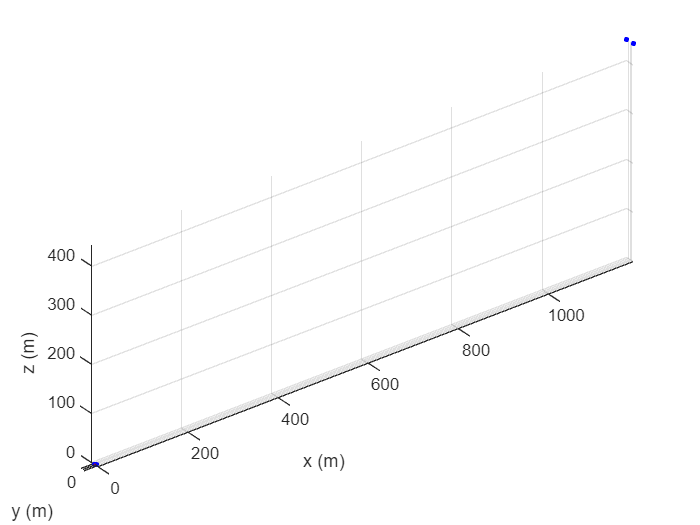

% ----------------Calculating unit vectors of members-----------------------

% getting unit vectors along each member
% (inboard - outboard coordinates) / magnitude
u_F_LCA_F = (F_LCA_O-F_LCA_IF)/(norm(F_LCA_O-F_LCA_IF)); % the same as "n" shown in the matrix A
u_F_LCA_R = (F_LCA_O-F_LCA_IR)/(norm(F_LCA_O-F_LCA_IR));
u_F_UCA_F = (F_UCA_O-F_UCA_IF)/(norm(F_UCA_O-F_UCA_IF));
u_F_UCA_R = (F_UCA_O-F_UCA_IR)/(norm(F_UCA_O-F_UCA_IR));
u_F_PR = (F_PR_O-F_PR_I)/(norm(F_PR_O-F_PR_I));
u_F_S = (F_SC-F_RS)/(norm(F_SC-F_RS));
u_F_TR = (F_TR_O-F_TR_I)/(norm(F_TR_O-F_TR_I));

u_R_LCA_F = (R_LCA_O-R_LCA_IF)/(norm(R_LCA_O-R_LCA_IF)); % the same as "n" shown in the matrix A
u_R_LCA_R = (R_LCA_O-R_LCA_IR)/(norm(R_LCA_O-R_LCA_IR));
u_R_UCA_F = (R_UCA_O-R_UCA_IF)/(norm(R_UCA_O-R_UCA_IF));
u_R_UCA_R = (R_UCA_O-R_UCA_IR)/(norm(R_UCA_O-R_UCA_IR));
u_R_PR = (R_PR_O-R_PR_I)/(norm(R_PR_O-R_PR_I));
u_R_S = (R_SC-R_RS)/(norm(R_SC-R_RS));
u_R_TR = (R_TR_O-R_TR_I)/(norm(R_TR_O-R_TR_I));

% plotting unit vectors for front members
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), u_F_LCA_F(x), u_F_LCA_F(y), u_F_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), u_F_LCA_R(x), u_F_LCA_R(y), u_F_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), u_F_UCA_F(x), u_F_UCA_F(y), u_F_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), u_F_UCA_R(x), u_F_UCA_R(y), u_F_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), u_F_PR(x), u_F_PR(y), u_F_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_SC(x), F_SC(y), F_SC(z), u_F_S(x), u_F_S(y), u_F_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), u_F_TR(x), u_F_TR(y), u_F_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% plotting unit vectors for rear members
quiver3(R_LCA_IF(x), R_LCA_IF(y), R_LCA_IF(z), u_R_LCA_F(x), u_R_LCA_F(y), u_R_LCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_LCA_IR(x), R_LCA_IR(y), R_LCA_IR(z), u_R_LCA_R(x), u_R_LCA_R(y), u_R_LCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IF(x), R_UCA_IF(y), R_UCA_IF(z), u_R_UCA_F(x), u_R_UCA_F(y), u_R_UCA_F(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_UCA_IR(x), R_UCA_IR(y), R_UCA_IR(z), u_R_UCA_R(x), u_R_UCA_R(y), u_R_UCA_R(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_PR_I(x), R_PR_I(y), R_PR_I(z), u_R_PR(x), u_R_PR(y), u_R_PR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_SC(x), R_SC(y), R_SC(z), u_R_S(x), u_R_S(y), u_R_S(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);
quiver3(R_TR_I(x), R_TR_I(y), R_TR_I(z), u_R_TR(x), u_R_TR(y), u_R_TR(z), 'color', 'magenta', 'AutoScaleFactor', unitvect_scalefactor, 'LineWidth', unitvect_linewidth);

% ----------------Calculating Moments--------------------------------------


% getting moment arm from MomCent for each member
d_F_LCA_IR = F_LCA_IR-MC;
d_F_LCA_IF = F_LCA_IF-MC;
d_F_UCA_IR = F_UCA_IR-MC;
d_F_UCA_IF = F_UCA_IF-MC;
d_F_TR = F_TR_I-MC;
d_F_PR = F_PR_I-MC;
d_F_TP = F_TP-MC;

d_R_LCA_IR = R_LCA_IR-MC;
d_R_LCA_IF = R_LCA_IF-MC;
d_R_UCA_IR = R_UCA_IR-MC;
d_R_UCA_IF = R_UCA_IF-MC;
d_R_TR = R_TR_I-MC;
d_R_PR = R_PR_I-MC;
d_R_TP = R_TP-MC;

% Moments for each member about the moment center
M_F_UCA_IF = cross(d_F_UCA_IF, u_F_UCA_F);
M_F_UCA_IR = cross(d_F_UCA_IR, u_F_UCA_R);
M_F_LCA_IF = cross(d_F_LCA_IF, u_F_LCA_F);
M_F_LCA_IR = cross(d_F_LCA_IR, u_F_LCA_R);
M_F_PR = cross(d_F_PR, u_F_PR);
M_F_TR = cross(d_F_TR, u_F_TR);

M_R_UCA_IF = cross(d_R_UCA_IF, u_R_UCA_F);
M_R_UCA_IR = cross(d_R_UCA_IR, u_R_UCA_R);
M_R_LCA_IF = cross(d_R_LCA_IF, u_R_LCA_F);
M_R_LCA_IR = cross(d_R_LCA_IR, u_R_LCA_R);
M_R_PR = cross(d_R_PR, u_R_PR);
M_R_TR = cross(d_R_TR, u_R_TR);

## 1st Load Case: 0g braking, 0g cornering, 2g bump

% Setting tire loads as per the load case
F_FO = F_0g_0g_2g(1,:);

Unrecognized function or variable 'F_0g_0g_2g'.

F_FI = F_0g_0g_2g(2,:);
F_RO = F_0g_0g_2g(3,:);
F_RI = F_0g_0g_2g(4,:);

% Plotting x,y,z components of contact patch force
quiver3(F_TP(x), F_TP(y), F_TP(z), F_FO(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, F_FO(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), F_TP(y), F_TP(z), 0, 0, F_FO(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(F_TP(x), -F_TP(y), F_TP(z), F_FI(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), -F_TP(y), F_TP(z), 0, F_FI(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(F_TP(x), -F_TP(y), F_TP(z), 0, 0, F_FI(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(R_TP(x), R_TP(y), R_TP(z), F_RO(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), R_TP(z), 0, F_RO(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), R_TP(z), 0, 0, F_RO(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);

quiver3(R_TP(x), R_TP(y), -R_TP(z), F_RI(x), 0, 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), -R_TP(z), 0, F_RI(y), 0, 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
quiver3(R_TP(x), R_TP(y), -R_TP(z), 0, 0, F_RI(z), 'Color', 'cyan', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);


% Moments around moment center from input forces at tire patch
M_F_Fx = cross(d_F_TP,[F_FO(x); 0; 0]);
M_F_Fy = cross(d_F_TP,[0; F_FO(y); 0]);
M_F_Fz = cross(d_F_TP,[0; 0; F_FO(z)]);

% ----------------Setting up Matrix to solve-------------------------------


% 6x6 matrix from sum of forces and sum of moments about MomCent
A = [u_F_UCA_F(x),    u_F_UCA_R(x),     u_F_LCA_F(x),     u_F_LCA_R(x),     u_F_PR(x),     u_F_TR(x);
    u_F_UCA_F(y),    u_F_UCA_R(y),     u_F_LCA_F(y),     u_F_LCA_R(y),     u_F_PR(y),     u_F_TR(y);
    u_F_UCA_F(z),    u_F_UCA_R(z),     u_F_LCA_F(z),     u_F_LCA_R(z),     u_F_PR(z),     u_F_TR(z);
    M_F_UCA_IF(x),   M_F_UCA_IR(x),    M_F_LCA_IF(x),    M_F_LCA_IR(x),    M_F_PR(x),    M_F_TR(x);
    M_F_UCA_IF(y),   M_F_UCA_IR(y),    M_F_LCA_IF(y),    M_F_LCA_IR(y),    M_F_PR(y),    M_F_TR(y);
    M_F_UCA_IF(z),   M_F_UCA_IR(z),    M_F_LCA_IF(z),    M_F_LCA_IR(z),    M_F_PR(z),    M_F_TR(z)];


% Make input matrix B=[-F(x); -F(y); -F(z); -M(x); -M(y); -M(z)]
B = [-F_FO(x); -F_FO(y); -F_FO(z); -(M_F_Fx(x)+M_F_Fy(x)+M_F_Fz(x)); -(M_F_Fx(y)+M_F_Fy(y)+M_F_Fz(y)); -(M_F_Fx(z)+M_F_Fy(z)+M_F_Fz(z))];


% ----------------Solve for Forces in Members------------------------------


F_mag = A\B;

% Formatting of F_mat: F_mat = [F_UCA_F; F_UCA_R; F_LCA_F; F_LCA_R; F_PR; F_TR]

% Each member force as a 3x1 vector
F_F_UCA_F = F_mag(1)*u_F_UCA_F;
F_F_UCA_R = F_mag(2)*u_F_UCA_R;
F_F_LCA_F = F_mag(3)*u_F_LCA_F;
F_F_LCA_R = F_mag(4)*u_F_LCA_R;
F_F_PR = F_mag(5)*u_F_PR;
F_F_TR = F_mag(6)*u_F_TR;

F_F_UCA_O = F_F_UCA_F + F_F_UCA_R + F_F_PR;
% norm(F_F_UCA_O(1:2))
F_F_LCA_O = F_F_LCA_F + F_F_LCA_R;
% norm(F_F_LCA_O)


% ---------------Solve for Forces in Rocker and Shock--------------------


% Moment arm from rocker pivot for pullrod and shock
d_F_RP_PR = F_PR_I - F_RP;
d_F_RP_RS = F_RS - F_RP;

% Moment about rocker pivot from pullrod input force
M_F_RP_PR = cross(d_F_RP_PR, F_F_PR);

% Moment about rocker pivot for shock
M_F_RP_RS = cross(d_F_RP_RS, u_F_S);

% Setting up matrix and solving
RP_A = [1 0 0 u_F_S(x)
        0 1 0 u_F_S(y)
        0 0 1 u_F_S(z)
        0 0 0 M_F_RP_RS(x)
        0 0 0 M_F_RP_RS(y)
        0 0 0 M_F_RP_RS(z)];

RP_B = [-F_F_PR(x); -F_F_PR(y); -F_F_PR(z); -M_F_RP_PR(x); -M_F_RP_PR(y); -M_F_RP_PR(z)];
RP_F_mag = RP_A\RP_B;

F_F_RP = RP_F_mag(1:3);
F_F_S = RP_F_mag(4)*u_F_S;

F_0g_0g_2g_Out = ["UCA Front" F_F_UCA_F; 
                  "UCA Rear" F_F_UCA_R;
                  "UCA Balljoint" F_F_UCA_O; 
                  "LCA Front" F_F_LCA_F;
                  "LCA Rear" F_F_LCA_R;
                  "LCA Balljoint" F_F_LCA_O;
                  "Pushrod" F_F_PR;
                  "Rocker pivot" F_F_RP';
                  "Shock" F_F_S;
                  "Steering Tie-rod" F_F_TR];


% ----------------Plotting Force vectors for Members-----------------------


% plotting Force vector along bottom front member
quiver3(F_LCA_IF(x), F_LCA_IF(y), F_LCA_IF(z), F_F_LCA_F(x), F_F_LCA_F(y), F_F_LCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along bottom rear member
quiver3(F_LCA_IR(x), F_LCA_IR(y), F_LCA_IR(z), F_F_LCA_R(x), F_F_LCA_R(y), F_F_LCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top front member
quiver3(F_UCA_IF(x), F_UCA_IF(y), F_UCA_IF(z), F_F_UCA_F(x), F_F_UCA_F(y), F_F_UCA_F(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along top rear member
quiver3(F_UCA_IR(x), F_UCA_IR(y), F_UCA_IR(z), F_F_UCA_R(x), F_F_UCA_R(y), F_F_UCA_R(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock member
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), F_F_PR(x), F_F_PR(y), F_F_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along tie rod
quiver3(F_TR_I(x), F_TR_I(y), F_TR_I(z), F_F_TR(x), F_F_TR(y), F_F_TR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along pull rod
quiver3(F_PR_I(x), F_PR_I(y), F_PR_I(z), F_F_PR(x), F_F_PR(y), F_F_PR(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector for rocker pivot
quiver3(F_RP(x), F_RP(y), F_RP(z), F_F_RP(x), F_F_RP(y), F_F_RP(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);
% plotting Force vector along shock
quiver3(F_SC(x), F_SC(y), F_SC(z), F_F_S(x), F_F_S(y), F_F_S(z), 'color', 'red', 'AutoScaleFactor', forcevect_scalefactor, 'LineWidth', forcevect_linewidth);